Submission for the 3. Deep Learning Assignment from Jens Settelmeier

lambda was searched in the range of 0.005 until 0.05 and best results were achieved with 0.01.

3 layer without Batchnormalisation

%% Assignment 3 DD2424 Deep Learning in Data Science at KTH 
% Author: Jens Settelmeier
%%

clc
clear all
%% Load Data

fprintf('Load Data\n');

Load Data



% Set Data Paths
trainPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_1.mat');
valPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_2.mat');
testPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/test_batch.mat');

% Define how much data should be used for validation and test in percentage
validation_ratio = 20;
test_ratio = 10;

% Shuffle the loaded data to make sure it is not initilized sorted 
shuffle = true;

% Load the data
%[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData(shuffle,trainPath,valPath,testPath);
[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData_fast(shuffle,validation_ratio,test_ratio,trainPath);

shuffle data...


%[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]= loadData_all( shuffle, validation_ratio,test_ratio);

%% Network (Hyper)parameters and Initializations

fprintf('Initialize Network Parameters \n');

Initialize Network Parameters 



numberOfClasses = 10; % number of classes
[d,N] = size(X_train); % dim of each picture 32*32*3

% configure the neurons per layer and number of layers
layers = [d,50,50,50,numberOfClasses]; % all layers except the input layers are count as layers in a k-layer network

% Penalty factor for Ridge Regression
lambda = 0.01;

% Initialize Weights and Biasesfalse
[W, b] = InitializeParamsDN(layers);

% Initialize Shift and Scale factors for Batch Normalisation
[gamma, beta] = Initialize_BN_ParamsDN2(layers);

% Max and Min for learning rate, adjusted by circle learning method
eta_max = 1e-1;
eta_min = 1e-5;

% Number of samples per Batch (Batch Size)
Batch_size = 100;

% Number of Epochs per circle
n_epochs = 15;

% Stepsize in circle learning
[~,NumberOfSamples] = size(X_train);
mutliple_fac = 2;
n_s = mutliple_fac*floor(NumberOfSamples/Batch_size);

% Random/shuffel Batches
SGD = true;

% Batchnormalisation on/off
Batchnormalization = false;

% (leaky) ReLu as activation
leakyReLuFactor = 0.01; % default: 0

% Train the Mini Batch by Gradient Descent
[epoch_accs, epoch_losses, eta_array, W,b,gamma, beta] = MiniBatchGD_ex41(X_train,Y_train, y_train, X_val,Y_val, y_val,Batch_size, eta_max, eta_min, n_epochs,n_s,W,b,lambda, gamma, beta,SGD,Batchnormalization,leakyReLuFactor);

Train the network
Testing done..




[max_acc,at_epoch]=max(epoch_accs(2,:))

max_acc = 0.4110

at_epoch = 9

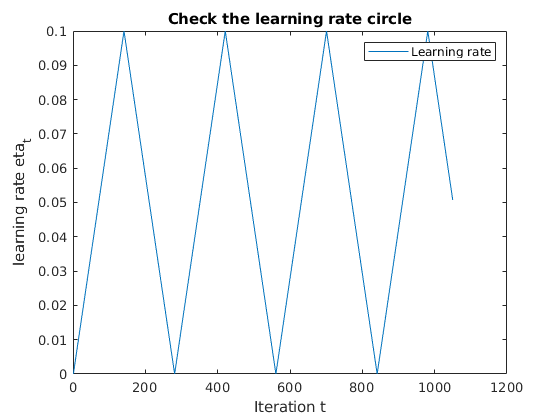


%% Plots

% learning rate circle
figure
plot(1:length(eta_array),eta_array)
title('Check the learning rate circle');
xlabel('Iteration t');
ylabel('learning rate eta_t');
legend('Learning rate');

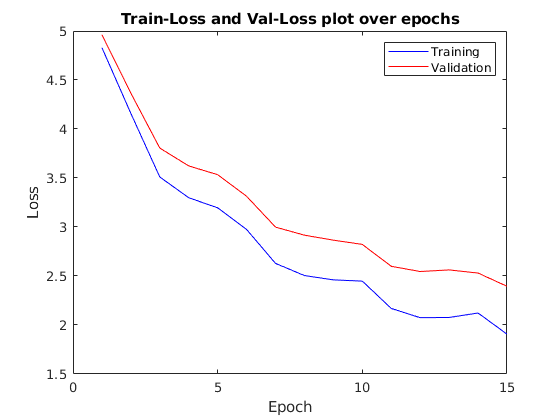


% Train-Loss and Val-Loss plot over epochs 
epochs = 1:length(epoch_losses(1,:));
figure
plot(epochs, epoch_losses(1,:), 'b', epochs, epoch_losses(2,:), 'r')
title('Train-Loss and Val-Loss plot over epochs');
xlabel('Epoch');
ylabel('Loss');
legend('Training','Validation');

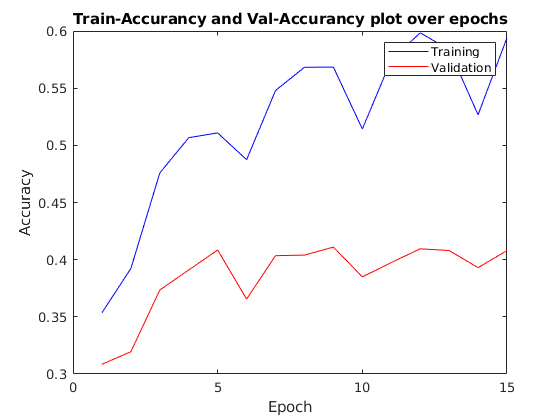


figure
plot(epochs, epoch_accs(1,:), 'b', epochs, epoch_accs(2,:), 'r')
title('Train-Accurancy and Val-Accurancy plot over epochs');
xlabel('Epoch');
ylabel('Accuracy');
legend('Training','Validation');

3 layer with Batch Normalisation

%% Assignment 3 DD2424 Deep Learning in Data Science at KTH 
% Author: Jens Settelmeier
%%

clc
clear all
%% Load Data

fprintf('Load Data\n');

Load Data



% Set Data Paths
trainPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_1.mat');
valPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_2.mat');
testPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/test_batch.mat');

% Define how much data should be used for validation and test in percentage
validation_ratio = 20;
test_ratio = 10;

% Shuffle the loaded data to make sure it is not initilized sorted 
shuffle = true;

% Load the data
%[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData(shuffle,trainPath,valPath,testPath);
%[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData_fast(shuffle, validation_ratio,test_ratio, trainPath);
[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]= loadData_all( shuffle, validation_ratio,test_ratio);

shuffle data...


%% Network (Hyper)parameters and Initializations

fprintf('Initialize Network Parameters \n');

Initialize Network Parameters 



numberOfClasses = 10; % number of classes
[d,N] = size(X_train); % dim of each picture 32*32*3

% configure the neurons per layer and number of layers
layers = [d,50,50,50,numberOfClasses]; % all layers except the input layers are count as layers in a k-layer network

% Penalty factor for Ridge Regression
lambda = 0.01;

% Initialize Weights and Biasesfalse
[W, b] = InitializeParamsDN(layers);

% Initialize Shift and Scale factors for Batch Normalisation
[gamma, beta] = Initialize_BN_ParamsDN2(layers);

% Max and Min for learning rate, adjusted by circle learning method
eta_max = 1e-1;
eta_min = 1e-5;

% Number of samples per Batch (Batch Size)
Batch_size = 100;

% Number of Epochs per circle
n_epochs = 15;

% Stepsize in circle learning
[~,NumberOfSamples] = size(X_train);
mutliple_fac = 2;
n_s = mutliple_fac*floor(NumberOfSamples/Batch_size);

% Random/shuffel Batches
SGD = true;

% Batchnormalisation on/off
Batchnormalization = true;

% (leaky) ReLu as activation
leakyReLuFactor = 0.01; % default: 0

% Train the Mini Batch by Gradient Descent
[epoch_accs, epoch_losses, eta_array, W,b,gamma, beta] = MiniBatchGD_ex42(X_train,Y_train, y_train, X_val,Y_val, y_val,Batch_size, eta_max, eta_min, n_epochs,n_s,W,b,lambda, gamma, beta,SGD,Batchnormalization,leakyReLuFactor);

Train the network
Testing done..




[max_acc,at_epoch]=max(epoch_accs(2,:))

max_acc = 0.4837

at_epoch = 12

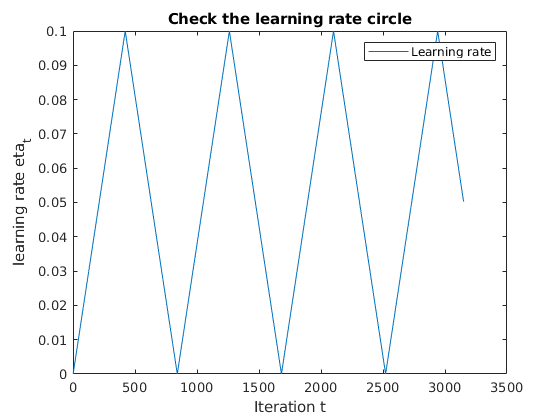


%% Plots

% learning rate circle
figure
plot(1:length(eta_array),eta_array)
title('Check the learning rate circle');
xlabel('Iteration t');
ylabel('learning rate eta_t');
legend('Learning rate');

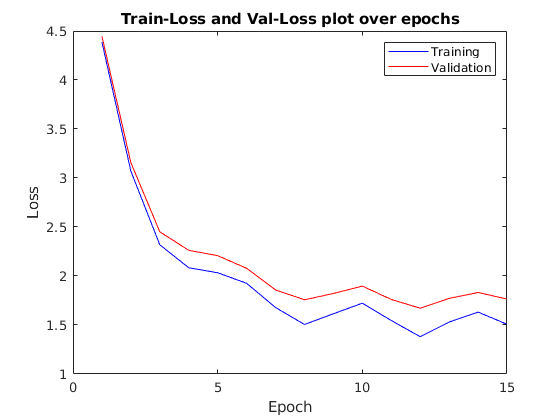


% Train-Loss and Val-Loss plot over epochs 
epochs = 1:length(epoch_losses(1,:));
figure
plot(epochs, epoch_losses(1,:), 'b', epochs, epoch_losses(2,:), 'r')
title('Train-Loss and Val-Loss plot over epochs');
xlabel('Epoch');
ylabel('Loss');
legend('Training','Validation');

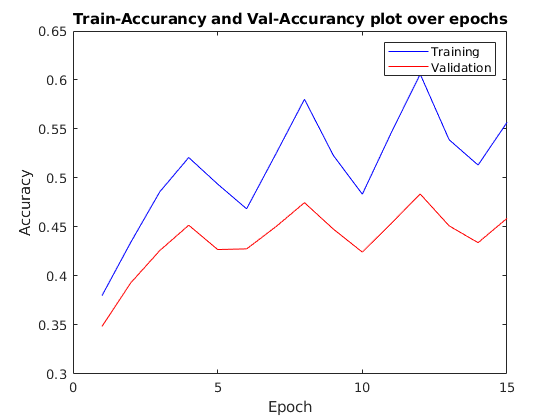


figure
plot(epochs, epoch_accs(1,:), 'b', epochs, epoch_accs(2,:), 'r')
title('Train-Accurancy and Val-Accurancy plot over epochs');
xlabel('Epoch');
ylabel('Accuracy');
legend('Training','Validation');

9 layer without Batch normalisation

%% Assignment 3 DD2424 Deep Learning in Data Science at KTH 
% Author: Jens Settelmeier
%%

clc
clear all
%% Load Data

fprintf('Load Data\n');

Load Data



% Set Data Paths
trainPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_1.mat');
valPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_2.mat');
testPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/test_batch.mat');

% Define how much data should be used for validation and test in percentage
validation_ratio = 20;
test_ratio = 10;

% Shuffle the loaded data to make sure it is not initilized sorted 
shuffle = true;

% Load the data
%[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData(shuffle,trainPath,valPath,testPath);
%[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData_fast(shuffle, validation_ratio,test_ratio, trainPath);
[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]= loadData_all( shuffle, validation_ratio,test_ratio);

shuffle data...


%% Network (Hyper)parameters and Initializations

fprintf('Initialize Network Parameters \n');

Initialize Network Parameters 



numberOfClasses = 10; % number of classes
[d,N] = size(X_train); % dim of each picture 32*32*3

% configure the neurons per layer and number of layers
layers = [d,50,30,20,20,10,10,10,10,numberOfClasses]; % all layers except the input layers are count as layers in a k-layer network

% Penalty factor for Ridge Regression
lambda = 0.01;

% Initialize Weights and Biasesfalse
[W, b] = InitializeParamsDN(layers);

% Initialize Shift and Scale factors for Batch Normalisation
[gamma, beta] = Initialize_BN_ParamsDN2(layers);

% Max and Min for learning rate, adjusted by circle learning method
eta_max = 1e-1;
eta_min = 1e-5;

% Number of samples per Batch (Batch Size)
Batch_size = 100;

% Number of Epochs per circle
n_epochs = 15;

% Stepsize in circle learning
[~,NumberOfSamples] = size(X_train);
mutliple_fac = 2;
n_s = mutliple_fac*floor(NumberOfSamples/Batch_size);

% Random/shuffel Batches
SGD = true;

% Batchnormalisation on/off
Batchnormalization = false;

% (leaky) ReLu as activation
leakyReLuFactor = 0.01; % default: 0

% Train the Mini Batch by Gradient Descent
[epoch_accs, epoch_losses, eta_array, W,b,gamma, beta] = MiniBatchGD_ex43(X_train,Y_train, y_train, X_val,Y_val, y_val,Batch_size, eta_max, eta_min, n_epochs,n_s,W,b,lambda, gamma, beta,SGD,Batchnormalization,leakyReLuFactor);

Train the network
Testing done..




[max_acc,at_epoch]=max(epoch_accs(2,:))

max_acc = 0.3822

at_epoch = 12


%% Plots

% learning rate circle
figure
plot(1:length(eta_array),eta_array)
title('Check the learning rate circle');
xlabel('Iteration t');
ylabel('learning rate eta_t');
legend('Learning rate');

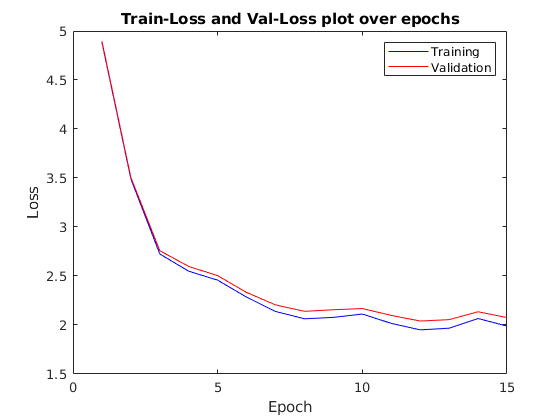


% Train-Loss and Val-Loss plot over epochs 
epochs = 1:length(epoch_losses(1,:));
figure
plot(epochs, epoch_losses(1,:), 'b', epochs, epoch_losses(2,:), 'r')
title('Train-Loss and Val-Loss plot over epochs');
xlabel('Epoch');
ylabel('Loss');
legend('Training','Validation');

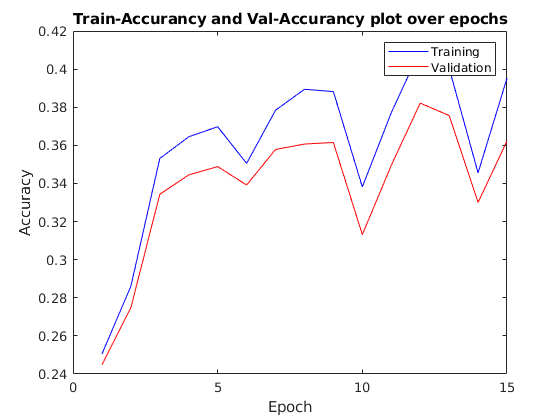


figure
plot(epochs, epoch_accs(1,:), 'b', epochs, epoch_accs(2,:), 'r')
title('Train-Accurancy and Val-Accurancy plot over epochs');
xlabel('Epoch');
ylabel('Accuracy');
legend('Training','Validation');

9 layer with Batch normalisation

%% Assignment 3 DD2424 Deep Learning in Data Science at KTH 
% Author: Jens Settelmeier
%%

clc
clear all
%% Load Data

fprintf('Load Data\n');

Load Data



% Set Data Paths
trainPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_1.mat');
valPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_2.mat');
testPath = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/test_batch.mat');

% Define how much data should be used for validation and test in percentage
validation_ratio = 20;
test_ratio = 10;

% Shuffle the loaded data to make sure it is not initilized sorted 
shuffle = true;

% Load the data
%[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData(shuffle,trainPath,valPath,testPath);
%[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData_fast(shuffle, validation_ratio,test_ratio, trainPath);
[X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]= loadData_all( shuffle, validation_ratio,test_ratio);

shuffle data...


%% Network (Hyper)parameters and Initializations

fprintf('Initialize Network Parameters \n');

Initialize Network Parameters 



numberOfClasses = 10; % number of classes
[d,N] = size(X_train); % dim of each picture 32*32*3

% configure the neurons per layer and number of layers
layers = [d,50,30,20,20,10,10,10,10,numberOfClasses]; % all layers except the input layers are count as layers in a k-layer network

% Penalty factor for Ridge Regression
lambda = 0.01;

% Initialize Weights and Biasesfalse
[W, b] = InitializeParamsDN(layers);

% Initialize Shift and Scale factors for Batch Normalisation
[gamma, beta] = Initialize_BN_ParamsDN2(layers);

% Max and Min for learning rate, adjusted by circle learning method
eta_max = 1e-1;
eta_min = 1e-5;

% Number of samples per Batch (Batch Size)
Batch_size = 100;

% Number of Epochs per circle
n_epochs = 15;

% Stepsize in circle learning
[~,NumberOfSamples] = size(X_train);
mutliple_fac = 2;
n_s = mutliple_fac*floor(NumberOfSamples/Batch_size);

% Random/shuffel Batches
SGD = true;

% Batchnormalisation on/off
Batchnormalization = true;

% (leaky) ReLu as activation
leakyReLuFactor = 0.01; % default: 0

% Train the Mini Batch by Gradient Descent
[epoch_accs, epoch_losses, eta_array, W,b,gamma, beta] = MiniBatchGD_ex44(X_train,Y_train, y_train, X_val,Y_val, y_val,Batch_size, eta_max, eta_min, n_epochs,n_s,W,b,lambda, gamma, beta,SGD,Batchnormalization,leakyReLuFactor);

Train the network
Testing done..




[max_acc,at_epoch]=max(epoch_accs(2,:))

max_acc = 0.4485

at_epoch = 12


%% Plots

% learning rate circle
figure
plot(1:length(eta_array),eta_array)
title('Check the learning rate circle');
xlabel('Iteration t');
ylabel('learning rate eta_t');
legend('Learning rate');

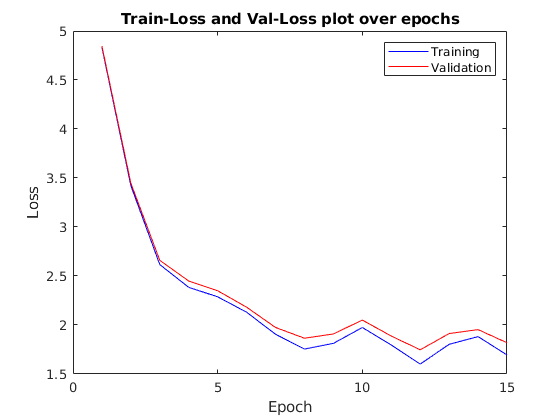


% Train-Loss and Val-Loss plot over epochs 
epochs = 1:length(epoch_losses(1,:));
figure
plot(epochs, epoch_losses(1,:), 'b', epochs, epoch_losses(2,:), 'r')
title('Train-Loss and Val-Loss plot over epochs');
xlabel('Epoch');
ylabel('Loss');
legend('Training','Validation');

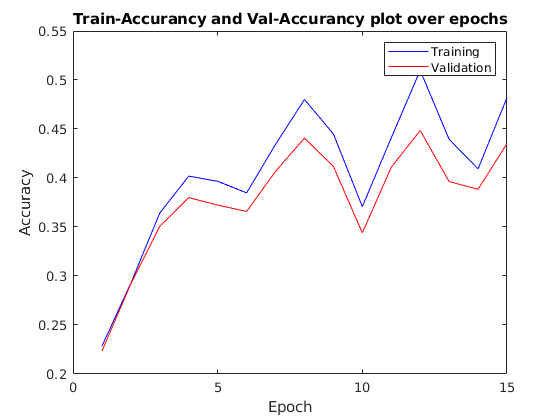


figure
plot(epochs, epoch_accs(1,:), 'b', epochs, epoch_accs(2,:), 'r')
title('Train-Accurancy and Val-Accurancy plot over epochs');
xlabel('Epoch');
ylabel('Accuracy');
legend('Training','Validation');

Functions

function data= shuffling(data)
%% Shuffels a set of Data
% Input:
%         data: data in matrix form
% Output:
%         data: data in matrix form shuffled
%%
[n,~] = size(data);
data = data(randperm(n),:);
end

function [train_data, val_data, test_data] = data_divider2(data, validation_ratio,test_ratio)
%% Divides a set of Data into subsets: Validation, Test and Train set.
% Input:
%       data: data in matrix form
%       validation_ratio: Percentage of the data that is used as
%                         Validation set
%       test_ratio: Percentage of the data that is used as Test set
% Output:
%       train_data: the remaining data beside val and test set
%       val_data: Validation set
%       test_data: Test set
%%

[n,~] = size(data);

validation_amount = round(n * validation_ratio/100);
test_amount = round(n * test_ratio/100);

data_indizies = 1:n;

tmp = randperm(length(data_indizies),validation_amount);
val_indizies = data_indizies(tmp);

data_indizies = setdiff(data_indizies,val_indizies);
tmp = randperm(length(data_indizies),test_amount);
test_indizies = data_indizies(tmp);

data_indizies= setdiff(data_indizies,test_indizies);

test_data = data(test_indizies,:);
val_data = data(val_indizies,:);
train_data = data(data_indizies,:);
end


function [X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData_fast( shuffle, validation_ratio,test_ratio, Path)
%% Loads Data for the Assignment (a subset)
% Input:
%       Path: data 
%       validation_ratio: Percentage of the data that is used as
%                         Validation set
%       test_ratio: Percentage of the data that is used as Test set
%       shuffle (logical): on/off shuffling the data
% Output:
%       X_train: Train input
%       Y_train: OneHot Lable vector of train data
%       y_train: class-lable of train data
%
%       X_val: Val input
%       Y_val: OneHot Lable vector of val data
%       y_val: class-lable of val data
%
%       X_test: Test input
%       Y_test: OneHot Lable vector of test data
%       y_test: class-lable of test data
%%

Data = LoadBatch(Path);
Input = Data{1}'; OneHot = Data{2}'; Lable = double(Data{3});
[~,dim_col_Input] = size(Input);
[~,dim_col_OneHot] = size(OneHot);

Data_Lable_OneHot = [Input,OneHot,Lable];

if shuffle == true
    fprintf('shuffle data...\n');
    Data_Lable_OneHot = shuffling(Data_Lable_OneHot);
else
end

[train_data, val_data, test_data] = data_divider2(Data_Lable_OneHot, validation_ratio,test_ratio);

X_train = train_data(:,1:dim_col_Input)';
Y_train = train_data(:,dim_col_Input+1:dim_col_Input + dim_col_OneHot)';
y_train = train_data(:,end);

X_val = val_data(:,1:dim_col_Input)';
Y_val = val_data(:,dim_col_Input+1:dim_col_Input + dim_col_OneHot)';
y_val = val_data(:,end);

X_test = test_data(:,1:dim_col_Input)';
Y_test = test_data(:,dim_col_Input+1:dim_col_Input + dim_col_OneHot)';
y_test = test_data(:,end);

end


function [X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData_all( shuffle, validation_ratio,test_ratio)
%% Loads Data for the Assignment (all)
% Input:
%       Path: data 
%       validation_ratio: Percentage of the data that is used as
%                         Validation set
%       test_ratio: Percentage of the data that is used as Test set
%       shuffle (logical): on/off shuffling the data
% Output:
%       X_train: Train input
%       Y_train: OneHot Lable vector of train data
%       y_train: class-lable of train data
%
%       X_val: Val input
%       Y_val: OneHot Lable vector of val data
%       y_val: class-lable of val data
%
%       X_test: Test input
%       Y_test: OneHot Lable vector of test data
%       y_test: class-lable of test data
%%
Path1 = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_1.mat');
Data1 = LoadBatch(Path1);
X_train1 = Data1{1}; Y_train1 = Data1{2}; y_train1 = double(Data1{3});

Path2 = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_2.mat');
Data2 = LoadBatch(Path2);
X_train2 = Data2{1}; Y_train2 = Data2{2}; y_train2 = double(Data2{3});

Path3 = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_3.mat');
Data3 = LoadBatch(Path3);
X_train3 = Data3{1}; Y_train3 = Data3{2}; y_train3 = double(Data3{3});

Path4 = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_4.mat');
Data4 = LoadBatch(Path4);
X_train4 = Data4{1}; Y_train4 = Data4{2}; y_train4 = double(Data4{3});

Path5 = load('/media/sneey/Linux_Vol/Assignment_1/Assignment_2/DirName/Datasets/cifar-10-batches-mat/data_batch_5.mat');
Data5 = LoadBatch(Path5);
X_train5 = Data5{1}; Y_train5 = Data5{2}; y_train5 = double(Data5{3});

Input = [X_train1,X_train2,X_train3]';%,X_train4,X_train5]';
OneHot =[Y_train1,Y_train2,Y_train3]';%,Y_train4,Y_train5]';
Lable = [y_train1;y_train2;y_train3];%;y_train4;y_train5];

[~,dim_col_Input] = size(Input);
[~,dim_col_OneHot] = size(OneHot);

Data_Lable_OneHot = [Input,OneHot,Lable];

if shuffle == true
    fprintf('shuffle data...\n');
    Data_Lable_OneHot = shuffling(Data_Lable_OneHot);
else
end

[train_data, val_data, test_data] = data_divider2(Data_Lable_OneHot, validation_ratio,test_ratio);

X_train = train_data(:,1:dim_col_Input)';
Y_train = train_data(:,dim_col_Input+1:dim_col_Input + dim_col_OneHot)';
y_train = train_data(:,end);

X_val = val_data(:,1:dim_col_Input)';
Y_val = val_data(:,dim_col_Input+1:dim_col_Input + dim_col_OneHot)';
y_val = val_data(:,end);

X_test = test_data(:,1:dim_col_Input)';
Y_test = test_data(:,dim_col_Input+1:dim_col_Input + dim_col_OneHot)';
y_test = test_data(:,end);

end


function [X_train,Y_train,y_train,X_val,Y_val,y_val,X_test,Y_test,y_test]=loadData(shuffel, trainPath,valPath,testPath)
%% Loads Data for the Assignment (all)
% Input:
%       trainPath: data for training
%       valPath: data for validation
%       testPath: data for testing
%       shuffle (logical): unused
% Output:
%       X_train: Train input
%       Y_train: OneHot Lable vector of train data
%       y_train: class-lable of train data
%
%       X_val: Val input
%       Y_val: OneHot Lable vector of val data
%       y_val: class-lable of val data
%
%       X_test: Test input
%       Y_test: OneHot Lable vector of test data
%       y_test: class-lable of test data
%%
B = LoadBatch(trainPath); C = LoadBatch(valPath); D = LoadBatch(testPath);

% X_train/val/test is input, Y_train/val/test is lable and y_train/val/test
% is the corresponding one-hot-vector
X_train = B{1}; Y_train = B{2}; y_train = B{3};
X_val = C{1}; Y_val = C{2}; y_val = C{3};
X_test = D{1}; Y_test = D{2}; y_test = D{3};

end

function B = LoadBatch(data)
%% Loads a batch of Data and normalize it
% Input:
%       data: data in matrix form
% Output:
%       B: normalized data as Batch
%%

% Normalize the data
    X = (double(data.data))';
    mean_X = mean(X,2);
    std_X = std(X,0,2);
    X = X - repmat(mean_X, [1, size(X,2)]);
    X = X ./ repmat(std_X, [1, size(X,2)]);
    
    y = data.labels;
    K = 10; % number of classes
    Y = zeros(K,length(y));
    for i=1:length(y)
        j = y(i)+1; % matlab starts counting at 1 and not zero. so class 0 corresponds to column 1
        Y(j,i)=1;
    end
    B = {X,Y,y};
end   


function [gamma,beta] = Initialize_BN_ParamsDN2(layers)
%% Initializes the scale and shift parameter for the Batch Normalisation (BN)
% Input:
%         layers: vector that specifies the number of neurones per layer
% Output:
%       gamma: Initialized gammas for BN scaling
%       beta: Initialized betas for BN shifting
%%

k = length(layers)-1;
gamma = cell(1,k-1);
beta = cell(1,k-1);

% Initialize parameters
for i = 1:k-1    
    gamma{i} = ones(layers(i+1),1);
    beta{i} = zeros(layers(i+1),1);    
end

end


function [S_oBN,S_BN, v,mu,p,X_l] = EvaluateClassifier(X,W,b,gamma,beta,Batchnormalization, leakyReLuFactor)
%% Forward the Data through the K-layer Network
% Input: 
%       X: Input data
%       W (cell): Weights of the layers
%       b (cell): Biases of the layers
%       gamma (cell): Scaling for BN
%       beta (cell): Shifting for BN
%       Batchnormalisation (logical): on/off BN
%       leakyReLuFactor: factor for the (leaky) ReLu activation
% Output:
%       S_oBN (cell): Layer-outputs w/o BN and Activation
%       S_BN (cell): Layer-outputs w/ BN and w/o Activation
%       X_l (cell): Layer-output w/ BN and Activation
%       mu (double): Mean of S_oBN
%       v (double): variance of S_oBN
%       p: prediction of the Network due softmax activation
%%

[~,N] = size(X); % N = n_b
numLayers = length(W);

% fixing a 0 index case...
X_l_dummy = cell(1,numLayers+1);
X_l_dummy{1} = X;

% Placeholders for acceleration
X_l = cell(1,numLayers-1);
S_BN = cell(1,numLayers-1);
S_oBN = cell(1,numLayers-1);
mu = cell(1,numLayers-1);
v = cell(1,numLayers-1);

%% Forward pass
% first k-1 layers
for i=1:numLayers-1
    b_tmp = repmat(b{i},1,N); 
    S = W{i}*X_l_dummy{i} + b_tmp;
    S_oBN{i} = S;
    
    if Batchnormalization==true
        %% Batchnormalization part
        
        % Mean for Normalisation
        mu_tmp = 1/N * sum(S,2);
        mu{i} = mu_tmp;
        
        % Variance for Normalisation
        v_tmp = 1/N * sum((S-mu_tmp).^2,2);
        v{i} = v_tmp;
        
        % Normalisation of the Batch
        S_hat = BatchNormalize(S,mu_tmp,v_tmp);
        S_BN{i} = S_hat;
        
        % Typical shifting and scaling during Batchnormalisierung
        [~,col_tmp] = size(S_hat);
        gamma_tmp = repmat(gamma{i},1,col_tmp);
        beta_tmp = repmat(beta{i},1,col_tmp);
        S_tilde = gamma_tmp.*S_hat + beta_tmp;

    else
        S_tilde = S;
    end
    
    % Activation with leaky ReLu and leaky factor 0.01.
    X_l{i} = max(leakyReLuFactor*S_tilde, S_tilde);
    X_l_dummy{i+1} = X_l{i};
end
% Last layer k
Sk = W{numLayers} * X_l{numLayers-1} + repmat(b{numLayers},1,N); % X_l{numLayers-1} = X_l_dummy{numLayers}

% Softmax
p = exp(Sk)./ sum(exp(Sk));  
end


function [grad_W, grad_b,grad_gamma,grad_beta] = ComputeGradientsDN(S_oBN,S_BN,v,mu,X_0, Y, P, W, lambda, X_l, gamma, Batchnormalization)
%% Compute Gradients for weight update
% Input: 
%       S_oBN: un-normalised Batch, Mean mu,
%       mu (double): Mean of s
%       v (double): variance of s
%       X_0: Input data of the Network
%       Y: One-Hot Vectors 
%       P: Prediction of forward Pass
%       W (cell): Weights
%       lambda: Ridge Regression penalty factor
%       X_l (cell): Layer Activations
%       gamma: Scaling factor for the Batch Normalisation
%       Batchnormalization (logical): BN on or off  
% Output:
%       grad_W: Gradients regarding the weights W
%       grad_b: Gradients regarding the biasses b
%       grad_gamma: Gradients regarding the gammas
%       grad_betas: Gradients regarding the betas
%%
% Gradienten computation in Matrix-Vector style
G_batch = -(Y -P);
numLayers = length(W);
[~,n_b] = size(X_l{end}); %könnte auch Y size genommen werden

% Placeholders for acceleration
grad_W = cell(1,numLayers);
grad_b = cell(1,numLayers);
grad_gamma = cell(1,numLayers);
grad_beta = cell(1,numLayers);

% layer k gradients
grad_W{numLayers} = 1/n_b * G_batch * X_l{numLayers-1}' + 2*lambda * W{numLayers};
grad_b{numLayers} = 1/n_b * G_batch * ones(n_b,1);
G_batch = W{numLayers}' * G_batch;
G_batch = G_batch .* (X_l{numLayers-1}>0);

% k-1 layers gradients
for i = (numLayers-1):-1:1
    if Batchnormalization == true
        %% Gradients of shifting and scaling parameter of Batch Normalisation
        
        % 1. Compute gradient for the scale and offset parameters for layer l:
        grad_gamma{i} = 1/n_b * ( G_batch .* S_BN{i})*ones(n_b,1);
        grad_beta{i} = 1/n_b * G_batch * ones(n_b,1);
        
        % 2. Propagate the gradients through the scale and shift
        G_batch = G_batch .* (gamma{i}*ones(n_b,1)');  
        
        % 3. Propagate G_batch through the batch normalization
        G_batch = BatchNormBackPass(G_batch, S_oBN{i}, mu{i},v{i});
    else
    end        
    % 4. The gradients of J w.r.t. bias vector b_l and W_l
    if i ~=1
        tmp = X_l{i-1}';
    else
        tmp = X_0';
    end
    grad_W{i} = 1/n_b * G_batch * tmp + 2*lambda * W{i};
    grad_b{i} = 1/n_b * G_batch * ones(n_b,1);
    
    % 5. If l>1 progpagate G_{batch} to previous layer    
    if i>1
        G_batch = W{i}'*G_batch;
        G_batch = G_batch .* (X_l{i-1}>0);
    end
end
end


function J = ComputeCostDN(p,Y,lambda,W)
%% Compute Loss 
% Input: 
%       p: prediction of the Network due softmax activation
%       Y: Lables as One-Hot-Vectors
%       lambda: Ridge Regression penalty factor
% Output:
%       J: engery cost / loss
%%

% Ridge Regression part to regulate weights
l_cross = -log(diag(Y' * p));
tmp = 0;
for i=1:length(W)
    tmp = tmp +sum(sum(W{i}.^2));
end

% Energy function to minimize
J = 1/length(l_cross) * sum(l_cross) + lambda * tmp;
end


function acc = ComputeAccuracy(y,p)
%% Compute Accuracy of Network Prediction
% Input: 
%       p: prediction of the Network due softmax activation
%       y: Lables (classes)
% Output:
%       acc: Prediction Accuracy
%%

[~,k] = size(p);
[~,I] = max(p);
correct_samples = find(I' == (y+1));

acc = length(correct_samples)/k;
end


function [G_batch] = BatchNormBackPass(G_batch, S_oBN, mu,v)
%% Propagate Gradient Batch trhough Batch Normalisation
% Input: 
%       S_oBN (double): Layer-outputs w/o BN and Activation
%       mu (double): Mean of S_oBN
%       v (double): variance of S_oBN
%       G_batch: Gradient batch 
% Output:
%       G_batch: Gradient batch
%%

[~,n_b] = size(G_batch);    
sigma_1 = (v+eps).^(-0.5);
sigma_2 = (v+eps).^(-1.5);

G_1 = G_batch .*(sigma_1*ones(n_b,1)');
G_2 = G_batch .*(sigma_2*ones(n_b,1)');

D = S_oBN - mu * ones(n_b,1)';
c = (G_2 .*D)*ones(n_b,1);

G_batch = G_1 - 1/n_b * (G_1 * ones(n_b,1))*ones(n_b,1)' - 1/n_b*D .*(c*ones(n_b,1)');
end


function S = BatchNormalize(s, mu, v)
%% Normalises a Batch
% Input: 
%       s (double-Mat): un-normalised Batch, Mean mu,
%       mu (double): Mean of s
%       v (double): variance of s
% Output:
%       S (double-Mat): normalized Batch
%%

% Normalisation of the Batch
S = (diag(v + eps)^(-1/2) * (s - mu));
end


For 3 layer without Batchnormalisation

function [epoch_accs,epoch_losses, eta_array, Wstar, bstar, gamma_star, beta_star] = MiniBatchGD_ex41(X_train,Y_train, y_train, X_val,Y_val, y_val,Batch_size, eta_max, eta_min, n_epochs,n_s,W,b,lambda, gamma, beta,SGD,Batchnormalization,leakyReLuFactor)
fprintf('Train the network\n');
% Initialization
Wstar = W;
bstar = b;
gamma_star = gamma;
beta_star = beta;

[~,N] = size(X_train);  % number of total training samples
eta_delta = eta_max - eta_min; % n_ delta from eq (14)

epoch_loss_train =zeros(1,n_epochs);
epoch_loss_val = zeros(1,n_epochs);

epoch_acc_train = zeros(1,n_epochs);
epoch_acc_val = zeros(1,n_epochs);
eta_array = zeros(1,n_epochs * N/Batch_size);

% check if N/n_batch is integer
if N/Batch_size ~= round(N/Batch_size)
    fprintf(' N/n_batch is not an integer!')
end

%% Circle Training
eta_t = eta_min;
eta_index = 1;
t = 0;
for i=1:n_epochs 
    for j=1:N/Batch_size 
        
        %% Batch selection
        if SGD == true
            Batch_indizies = randperm(N,Batch_size);
            X_batch = X_train(:,Batch_indizies);
            Y_batch = Y_train(:,Batch_indizies);
        else
            j_start = (j-1)*Batch_size + 1;
            j_end = j*Batch_size;
            X_batch = X_train(:, j_start:j_end);
            Y_batch = Y_train(:, j_start:j_end);
        end
        
        %% Gradient evalutation for updating
        [S_oBN, S_BN, v,mu,P_batch,X_l] = EvaluateClassifier(X_batch,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
        [grad_W, grad_b,grad_gamma,grad_beta] = ComputeGradientsDN(S_oBN,S_BN,v,mu,X_batch, Y_batch, P_batch, Wstar, lambda,X_l, gamma_star,Batchnormalization);
        
        %% weight, bias, shift and scale Parameter update: Backward pass
        for layer=1:length(Wstar)
            Wstar{layer} = Wstar{layer} - eta_t * grad_W{layer};
        end
        
        for layer=1:length(bstar)
            bstar{layer} = bstar{layer} - eta_t * grad_b{layer};
        end
        
        if Batchnormalization == true
            for layer=1:length(beta_star)
                beta_star{layer} = beta_star{layer} - eta_t * grad_beta{layer};
            end
            for layer=1:length(gamma_star)
                gamma_star{layer} = gamma_star{layer} - eta_t * grad_gamma{layer};
            end
        else
        end
        
        %% step_size regularisation
        if t<=n_s
            eta_t = eta_min + t/n_s * eta_delta;
            
        elseif t<= 2*n_s
            eta_t = eta_max - (t-n_s)/n_s * eta_delta;
        end
        
        t = mod(t+1,2*n_s);

        eta_array(eta_index) = eta_t;
        eta_index = eta_index+1;        
    end
    
    %% compute cost on whole train and test set
    % Loss on Train set
    [~, ~, ~,~,P_train,~] = EvaluateClassifier(X_train,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
    epoch_loss_train(i) = ComputeCostDN(P_train,Y_train,lambda,Wstar);
    
    % Loss on Val set
    [~, ~, ~,~,P_val,~] = EvaluateClassifier(X_val,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
    epoch_loss_val(i) = ComputeCostDN(P_val, Y_val,lambda,Wstar);
    
    %% compute accuracy on whole train and test set
    epoch_acc_train(i) = ComputeAccuracy(y_train,P_train);
    epoch_acc_val(i) = ComputeAccuracy(y_val, P_val);
    
end
fprintf('Testing done..\n');
%% Structure results
epoch_losses = [epoch_loss_train;epoch_loss_val];
epoch_accs = [epoch_acc_train;epoch_acc_val];
end


For 3 layer with Batch Normalisation

function [epoch_accs,epoch_losses, eta_array, Wstar, bstar, gamma_star, beta_star] = MiniBatchGD_ex42(X_train,Y_train, y_train, X_val,Y_val, y_val,Batch_size, eta_max, eta_min, n_epochs,n_s,W,b,lambda, gamma, beta,SGD,Batchnormalization,leakyReLuFactor)
fprintf('Train the network\n');
% Initialization
Wstar = W;
bstar = b;
gamma_star = gamma;
beta_star = beta;

[~,N] = size(X_train);  % number of total training samples
eta_delta = eta_max - eta_min; % n_ delta from eq (14)

epoch_loss_train =zeros(1,n_epochs);
epoch_loss_val = zeros(1,n_epochs);

epoch_acc_train = zeros(1,n_epochs);
epoch_acc_val = zeros(1,n_epochs);
eta_array = zeros(1,n_epochs * N/Batch_size);

% check if N/n_batch is integer
if N/Batch_size ~= round(N/Batch_size)
    fprintf(' N/n_batch is not an integer!')
end

%% Circle Training
eta_t = eta_min;
eta_index = 1;
t = 0;
for i=1:n_epochs 
    for j=1:N/Batch_size 
        
        %% Batch selection
        if SGD == true
            Batch_indizies = randperm(N,Batch_size);
            X_batch = X_train(:,Batch_indizies);
            Y_batch = Y_train(:,Batch_indizies);
        else
            j_start = (j-1)*Batch_size + 1;
            j_end = j*Batch_size;
            X_batch = X_train(:, j_start:j_end);
            Y_batch = Y_train(:, j_start:j_end);
        end
        
        %% Gradient evalutation for updating
        [S_oBN, S_BN, v,mu,P_batch,X_l] = EvaluateClassifier(X_batch,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
        [grad_W, grad_b,grad_gamma,grad_beta] = ComputeGradientsDN(S_oBN,S_BN,v,mu,X_batch, Y_batch, P_batch, Wstar, lambda,X_l, gamma_star,Batchnormalization);
        
        %% weight, bias, shift and scale Parameter update: Backward pass
        for layer=1:length(Wstar)
            Wstar{layer} = Wstar{layer} - eta_t * grad_W{layer};
        end
        
        for layer=1:length(bstar)
            bstar{layer} = bstar{layer} - eta_t * grad_b{layer};
        end
        
        if Batchnormalization == true
            for layer=1:length(beta_star)
                beta_star{layer} = beta_star{layer} - eta_t * grad_beta{layer};
            end
            for layer=1:length(gamma_star)
                gamma_star{layer} = gamma_star{layer} - eta_t * grad_gamma{layer};
            end
        else
        end
        
        %% step_size regularisation
        if t<=n_s
            eta_t = eta_min + t/n_s * eta_delta;
            
        elseif t<= 2*n_s
            eta_t = eta_max - (t-n_s)/n_s * eta_delta;
        end
        
        t = mod(t+1,2*n_s);

        eta_array(eta_index) = eta_t;
        eta_index = eta_index+1;        
    end
    
    %% compute cost on whole train and test set
    % Loss on Train set
    [~, ~, ~,~,P_train,~] = EvaluateClassifier(X_train,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
    epoch_loss_train(i) = ComputeCostDN(P_train,Y_train,lambda,Wstar);
    
    % Loss on Val set
    [~, ~, ~,~,P_val,~] = EvaluateClassifier(X_val,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
    epoch_loss_val(i) = ComputeCostDN(P_val, Y_val,lambda,Wstar);
    
    %% compute accuracy on whole train and test set
    epoch_acc_train(i) = ComputeAccuracy(y_train,P_train);
    epoch_acc_val(i) = ComputeAccuracy(y_val, P_val);
    
end
fprintf('Testing done..\n');
%% Structure results
epoch_losses = [epoch_loss_train;epoch_loss_val];
epoch_accs = [epoch_acc_train;epoch_acc_val];
end


For 9 Layer without Batch Normalisation

%% Functionen

function [epoch_accs,epoch_losses, eta_array, Wstar, bstar, gamma_star, beta_star] = MiniBatchGD_ex43(X_train,Y_train, y_train, X_val,Y_val, y_val,Batch_size, eta_max, eta_min, n_epochs,n_s,W,b,lambda, gamma, beta,SGD,Batchnormalization,leakyReLuFactor)
fprintf('Train the network\n');
% Initialization
Wstar = W;
bstar = b;
gamma_star = gamma;
beta_star = beta;

[~,N] = size(X_train);  % number of total training samples
eta_delta = eta_max - eta_min; % n_ delta from eq (14)

epoch_loss_train =zeros(1,n_epochs);
epoch_loss_val = zeros(1,n_epochs);

epoch_acc_train = zeros(1,n_epochs);
epoch_acc_val = zeros(1,n_epochs);
eta_array = zeros(1,n_epochs * N/Batch_size);

% check if N/n_batch is integer
if N/Batch_size ~= round(N/Batch_size)
    fprintf(' N/n_batch is not an integer!')
end

%% Circle Training
eta_t = eta_min;
eta_index = 1;
t = 0;
for i=1:n_epochs 
    for j=1:N/Batch_size 
        
        %% Batch selection
        if SGD == true
            Batch_indizies = randperm(N,Batch_size);
            X_batch = X_train(:,Batch_indizies);
            Y_batch = Y_train(:,Batch_indizies);
        else
            j_start = (j-1)*Batch_size + 1;
            j_end = j*Batch_size;
            X_batch = X_train(:, j_start:j_end);
            Y_batch = Y_train(:, j_start:j_end);
        end
        
        %% Gradient evalutation for updating
        [S_oBN, S_BN, v,mu,P_batch,X_l] = EvaluateClassifier(X_batch,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
        [grad_W, grad_b,grad_gamma,grad_beta] = ComputeGradientsDN(S_oBN,S_BN,v,mu,X_batch, Y_batch, P_batch, Wstar, lambda,X_l, gamma_star,Batchnormalization);
        
        %% weight, bias, shift and scale Parameter update: Backward pass
        for layer=1:length(Wstar)
            Wstar{layer} = Wstar{layer} - eta_t * grad_W{layer};
        end
        
        for layer=1:length(bstar)
            bstar{layer} = bstar{layer} - eta_t * grad_b{layer};
        end
        
        if Batchnormalization == true
            for layer=1:length(beta_star)
                beta_star{layer} = beta_star{layer} - eta_t * grad_beta{layer};
            end
            for layer=1:length(gamma_star)
                gamma_star{layer} = gamma_star{layer} - eta_t * grad_gamma{layer};
            end
        else
        end
        
        %% step_size regularisation
        if t<=n_s
            eta_t = eta_min + t/n_s * eta_delta;
            
        elseif t<= 2*n_s
            eta_t = eta_max - (t-n_s)/n_s * eta_delta;
        end
        
        t = mod(t+1,2*n_s);

        eta_array(eta_index) = eta_t;
        eta_index = eta_index+1;        
    end
    
    %% compute cost on whole train and test set
    % Loss on Train set
    [~, ~, ~,~,P_train,~] = EvaluateClassifier(X_train,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
    epoch_loss_train(i) = ComputeCostDN(P_train,Y_train,lambda,Wstar);
    
    % Loss on Val set
    [~, ~, ~,~,P_val,~] = EvaluateClassifier(X_val,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
    epoch_loss_val(i) = ComputeCostDN(P_val, Y_val,lambda,Wstar);
    
    %% compute accuracy on whole train and test set
    epoch_acc_train(i) = ComputeAccuracy(y_train,P_train);
    epoch_acc_val(i) = ComputeAccuracy(y_val, P_val);
    
end
fprintf('Testing done..\n');
%% Structure results
epoch_losses = [epoch_loss_train;epoch_loss_val];
epoch_accs = [epoch_acc_train;epoch_acc_val];
end


For 9 Layer with Batch Normalization

%% Functionen

function [epoch_accs,epoch_losses, eta_array, Wstar, bstar, gamma_star, beta_star] = MiniBatchGD_ex44(X_train,Y_train, y_train, X_val,Y_val, y_val,Batch_size, eta_max, eta_min, n_epochs,n_s,W,b,lambda, gamma, beta,SGD,Batchnormalization,leakyReLuFactor)
fprintf('Train the network\n');
% Initialization
Wstar = W;
bstar = b;
gamma_star = gamma;
beta_star = beta;

[~,N] = size(X_train);  % number of total training samples
eta_delta = eta_max - eta_min; % n_ delta from eq (14)

epoch_loss_train =zeros(1,n_epochs);
epoch_loss_val = zeros(1,n_epochs);

epoch_acc_train = zeros(1,n_epochs);
epoch_acc_val = zeros(1,n_epochs);
eta_array = zeros(1,n_epochs * N/Batch_size);

% check if N/n_batch is integer
if N/Batch_size ~= round(N/Batch_size)
    fprintf(' N/n_batch is not an integer!')
end

%% Circle Training
eta_t = eta_min;
eta_index = 1;
t = 0;
for i=1:n_epochs 
    for j=1:N/Batch_size 
        
        %% Batch selection
        if SGD == true
            Batch_indizies = randperm(N,Batch_size);
            X_batch = X_train(:,Batch_indizies);
            Y_batch = Y_train(:,Batch_indizies);
        else
            j_start = (j-1)*Batch_size + 1;
            j_end = j*Batch_size;
            X_batch = X_train(:, j_start:j_end);
            Y_batch = Y_train(:, j_start:j_end);
        end
        
        %% Gradient evalutation for updating
        [S_oBN, S_BN, v,mu,P_batch,X_l] = EvaluateClassifier(X_batch,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
        [grad_W, grad_b,grad_gamma,grad_beta] = ComputeGradientsDN(S_oBN,S_BN,v,mu,X_batch, Y_batch, P_batch, Wstar, lambda,X_l, gamma_star,Batchnormalization);
        
        %% weight, bias, shift and scale Parameter update: Backward pass
        for layer=1:length(Wstar)
            Wstar{layer} = Wstar{layer} - eta_t * grad_W{layer};
        end
        
        for layer=1:length(bstar)
            bstar{layer} = bstar{layer} - eta_t * grad_b{layer};
        end
        
        if Batchnormalization == true
            for layer=1:length(beta_star)
                beta_star{layer} = beta_star{layer} - eta_t * grad_beta{layer};
            end
            for layer=1:length(gamma_star)
                gamma_star{layer} = gamma_star{layer} - eta_t * grad_gamma{layer};
            end
        else
        end
        
        %% step_size regularisation
        if t<=n_s
            eta_t = eta_min + t/n_s * eta_delta;
            
        elseif t<= 2*n_s
            eta_t = eta_max - (t-n_s)/n_s * eta_delta;
        end
        
        t = mod(t+1,2*n_s);

        eta_array(eta_index) = eta_t;
        eta_index = eta_index+1;        
    end
    
    %% compute cost on whole train and test set
    % Loss on Train set
    [~, ~, ~,~,P_train,~] = EvaluateClassifier(X_train,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
    epoch_loss_train(i) = ComputeCostDN(P_train,Y_train,lambda,Wstar);
    
    % Loss on Val set
    [~, ~, ~,~,P_val,~] = EvaluateClassifier(X_val,Wstar, bstar, gamma_star, beta_star,Batchnormalization,leakyReLuFactor);
    epoch_loss_val(i) = ComputeCostDN(P_val, Y_val,lambda,Wstar);
    
    %% compute accuracy on whole train and test set
    epoch_acc_train(i) = ComputeAccuracy(y_train,P_train);
    epoch_acc_val(i) = ComputeAccuracy(y_val, P_val);
    
end
fprintf('Testing done..\n');
%% Structure results
epoch_losses = [epoch_loss_train;epoch_loss_val];
epoch_accs = [epoch_acc_train;epoch_acc_val];
end
